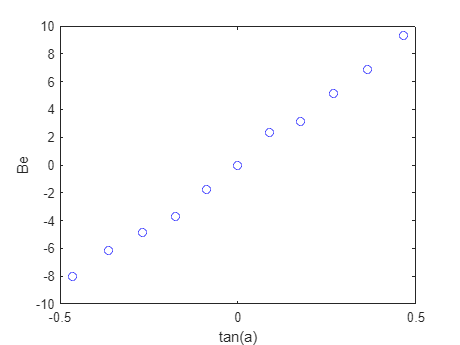

clear

tan_alpha = [-0.466, -0.364, -0.268, -0.176, -0.0875, 0, 0.0875, 0.176, 0.268, 0.364, 0.466];
Be = [-8.03, -6.15, -4.87, -3.68, -1.79, 0, 2.36, 3.14, 5.17, 6.89, 9.3];

plot(tan_alpha, Be, "o", "Color","b")
xlabel("tan(a)")
ylabel("Be")

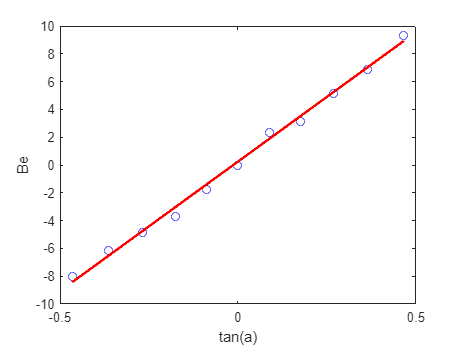


tan_alpha2 = [-0.466, -0.364, -0.268, -0.176, -0.0875, 0, 0.0875, 0.268, 0.364, 0.466];
Be2 = [-8.03, -6.15, -4.87, -3.68, -1.79, 0, 2.36, 5.17, 6.89, 9.3];


% Get coefficients of a line fit through the data.
coefficients = polyfit(tan_alpha2, Be2, 1);
% Create a new x axis with exactly 1000 points (or whatever you want).
xFit = linspace(min(tan_alpha2), max(tan_alpha2), 1000);
% Get the estimated yFit value for each of those 1000 new x locations.
yFit = polyval(coefficients , xFit);
plot(tan_alpha, Be, "o", "Color","b")
hold on; % Set hold on so the next plot does not blow away the one we just drew.
plot(xFit, yFit, 'r-', 'LineWidth', 2); % Plot fitted line.
hold off
xlabel("tan(a)")
ylabel("Be")

coefficients(1)

ans = 18.6311